# Diskret Stokastisk

## Eksempel 1 (unidrnd)

 

Uniformt fordelt: middelværdi = 0, varians = 10.

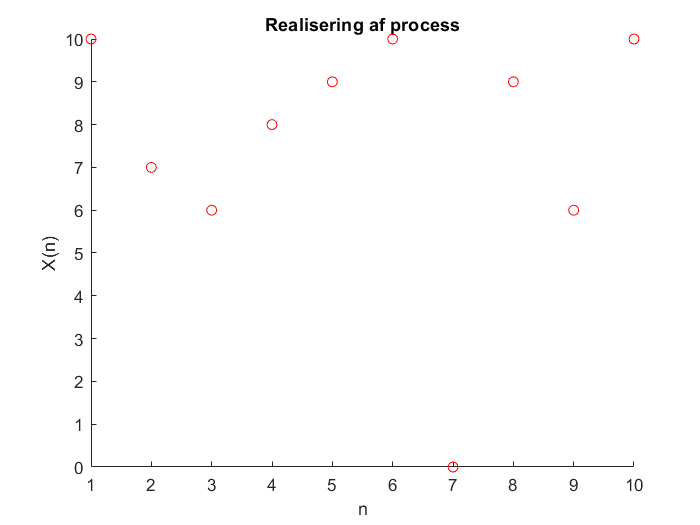

close all
clear all

N = 10; % Antal samples
max = 10;
% unidrnd Random arrays from the discrete uniform distribution.
% Returns an array of random numbers chosen uniformly from the set {1, 2, 3, ... ,N}
% Der skal bruges tal fra 0 til 10 derfor genereres tal mellem 1 og 11. Dernæst trækkes 1 fra.
Xn = unidrnd(max+1,1,N)-1; % max = 10, output = 1*N array
x = [1:1:N];
figure()
scatter(x,Xn,'or')
title("Realisering af process"); xlabel("n"); ylabel("X(n)");

## Eksempel 1 (randn)

 

Uniformt fordelt: middelværdi = 0, varians = 10.

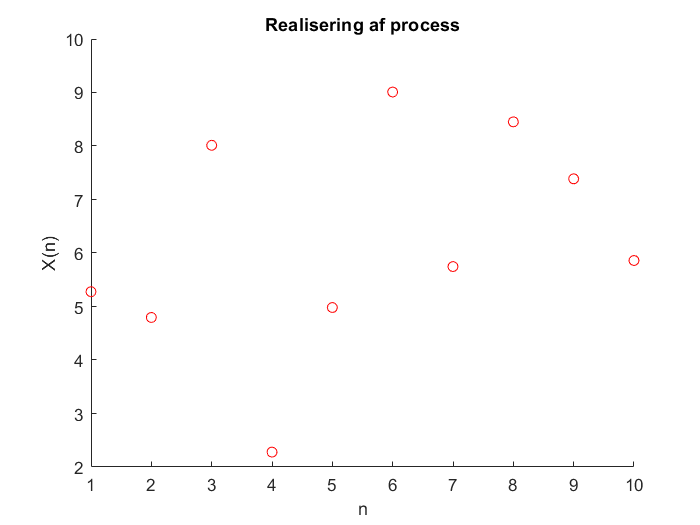

close all
clear all

N = 10; % Antal samples

% A ~ U(0,10)
a = 0; b = 10;
% R = rand(M,N) returns an N-by-N matrix containing pseudorandom values drawn
% from the standard uniform distribution on the open interval(0,1).
wn = a + (b-a).*rand(1,N);
x = [1:1:N];
figure()
scatter(x,wn,'or')
title("Realisering af process"); xlabel("n"); ylabel("X(n)");

## Eksempel 2

 

Gausisk fordelt: middelværdi = 0, varians = 1

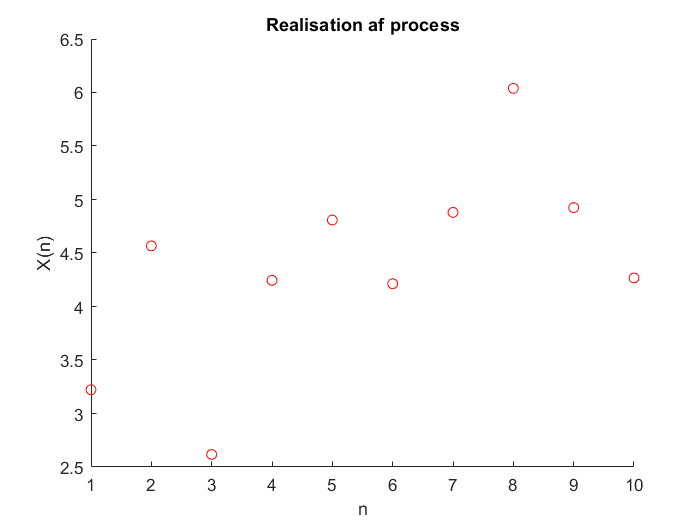

clear all
close all

N = 10; % Antal samples
mean = 0; variance = 1; sigma = sqrt(variance);
% R = normrnd(MU,SIGMA,[M,N,...]) returns an M-by-N-by-... array 
% of random numbers chosen from a normal distribution 
% with mean MU and standard deviation SIGMA.
w = normrnd(mean, sigma, [1 N]);
Xn = w + 4;
x = [1:1:N];
figure()
scatter(x, Xn,'or')
title("Realisation af process"); xlabel("n"); ylabel("X(n)");

## Eksempel 3

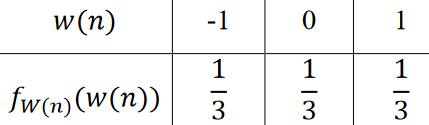

$W\left(n\right)$kan have følgende 3 værdier: 


$$\left(-1+0\ldotp 7\right)=-0\ldotp 3$$



$$\left(0+0\ldotp 7\right)=0\ldotp 7$$



$$\left(1+0\ldotp 7\right)=1\ldotp 7$$


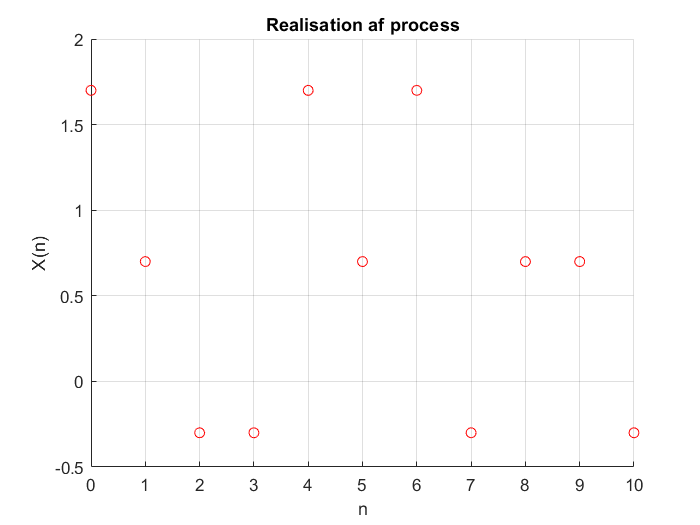

clear all
close all

% unidrnd returner et array med random værdier der er uniformt fordelt fra 
% {1, 2, ..., max}. For at få -1; 0; 1; shiftes arrayet ved at trække 2 fra!
% Der skal generes 3 værdier hvilket giver max = 3.
N = 11; % Antal samples
max = 3;
% Dernæst trækkes 2 fra igen, og der lægges 0.7 til ift. funktionen for X(n)
w = unidrnd(max, 1, N) - 2;
Xn = w + 0.7;
x = [0:1:N-1];
figure()
scatter(x, Xn, 'or')
grid on; 
xlabel("n"); ylabel("X(n)"); title("Realisation af process");

## Eksempel 4

 

$W\left(n\right)$kan have følgende 4 værdier: 


$$\left(2*0\right)-1=-1$$



$$\left(2*1\right)-1=1$$



$$\left(2*2\right)-1=3$$



$$\left(2*3\right)-1=5$$


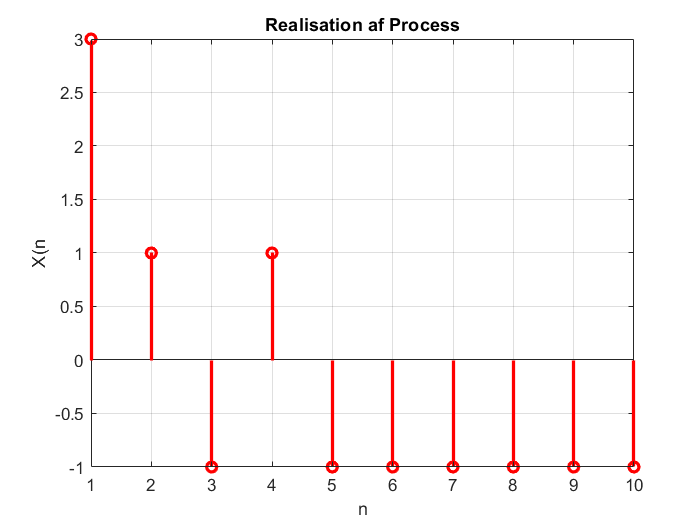

clear all
close all

% unidrnd returner et array med random værdier der er uniformt fordelt fra 
% {1, 2, ..., max}. For at få 0; 1; 2; 3; shiftes arrayet ved at trække 1 fra!
% Der skal generes 4 værdier hvilket giver max = 4.
N = 10; % Antal samples
max = 4;
w = unidrnd(max, 1, N) - 1;
Xn = (2*w)-1;
x = [1:1:N];
figure()
stem(x,Xn,'-r','LineWidth',2)
grid on
xlabel("n"); ylabel("X(n"); title("Realisation af process");

# Kontinuer Stokastisk

## Eksempel 1

clear all
close all

N = 5; % Antal realisationer
t = [0:7];
mu = 5; variance = 1; sigma = sqrt(variance);
w = normrnd(mu, sigma, [1 N+1])

w =     5.2882    3.4058    5.1102    5.7871    4.9978    5.0931


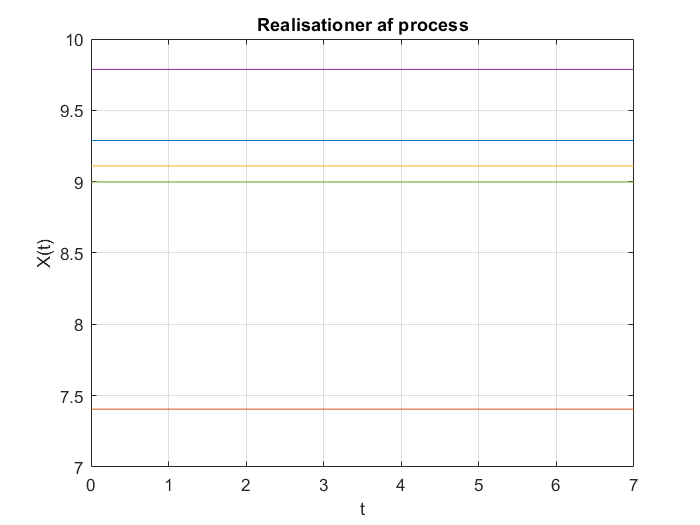

figure()
for i=1:N
    y = w(i)+4;
    plot(t, ones(1,length(t))*y);
    hold on
end
grid on
xlabel("t"); ylabel("X(t)"); title("Realisationer af process");

## Eksempel 2

                    

clear all
close all
t = 0:0.1:0.9;
mean = t; variance = 1; sigma = sqrt(variance);
w = normrnd(mean, sigma, [1 length(t)])

w =    -0.3782   -1.3827    0.1562    1.2608    2.1382    0.0698   -1.0273    0.8663    1.1763    0.6730


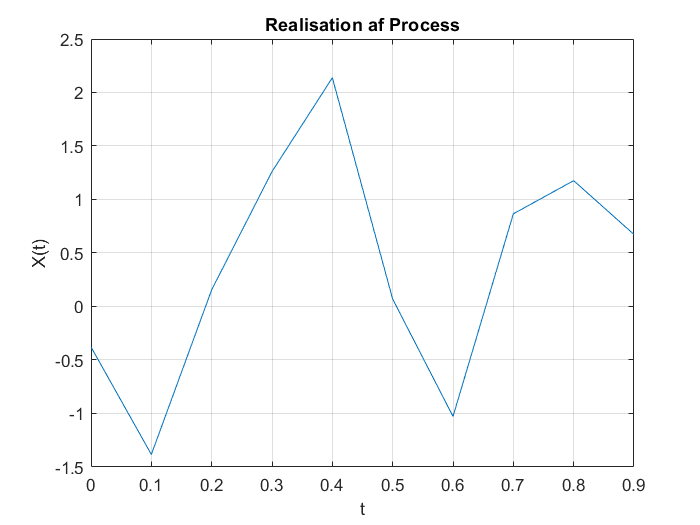

figure()
plot(t, w)
grid on
xlabel("t"); ylabel("X(t)"); title("Realisation af process");

## Eksempel 3

            

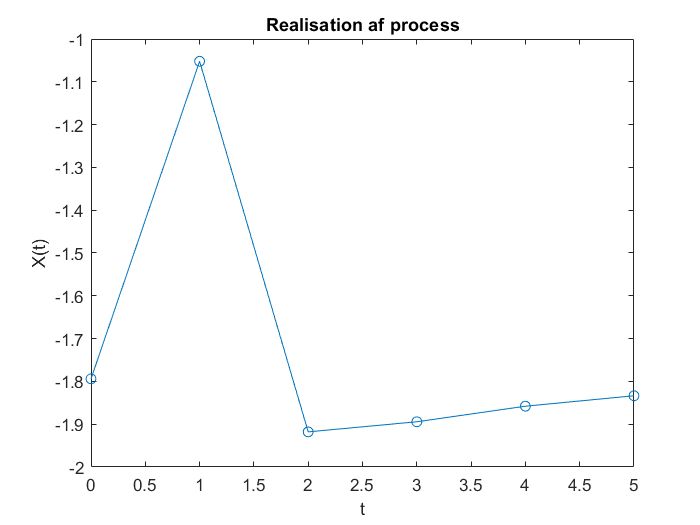

clear all
close all

N = 6; % Antal samples
% A ~ U(0,10)
a = -2; b = -1;
% R = rand(M,N) returns an N-by-N matrix containing pseudorandom values drawn
% from the standard uniform distribution on the open interval(0,1).
wn = a + (b-a).*rand(1,N);

x = 0:1:5;
figure()
plot(x, wn,'-o')
xlabel("t"); ylabel("X(t)"); title("Realisation af process");

## Eksempel 4

     

N kan uafhængigt antage værdierne 0 eller 1 med lige stor sandsynlighed

clear all
close all
x = 0:1:5; % Samples
N = 3; % Antal realisationer
% Først få værdierne til n
n = randi([0, 1], 1, 3)

n =      0     0     1


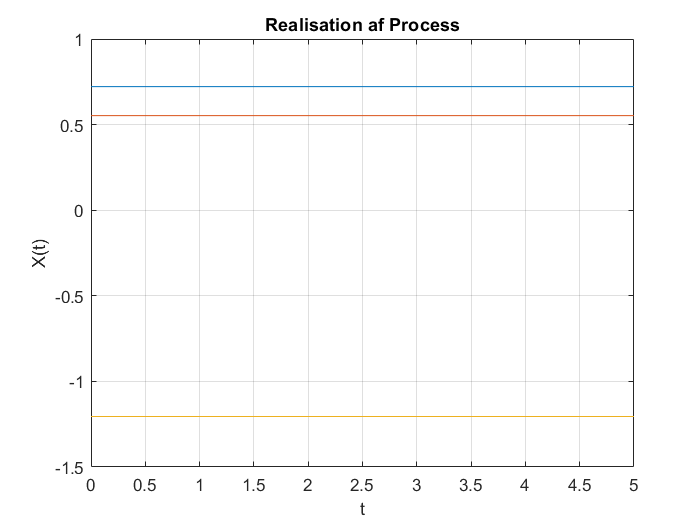

% Ud fra W~N(0; 0,25) kan vi udlede:
mean = 0; variance = 0.25; sigma = sqrt(variance);

% Få værdierne til w
w = randn(1, N) * sigma;
figure()
for i = 1:N
    y = (-1)^n(i) + w(i);
    plot(x, ones(1,length(x))*y);
    hold on
end
grid on;
xlabel("t"); ylabel("X(t)"); title("Realisation af process");

## Eksempel 5

     

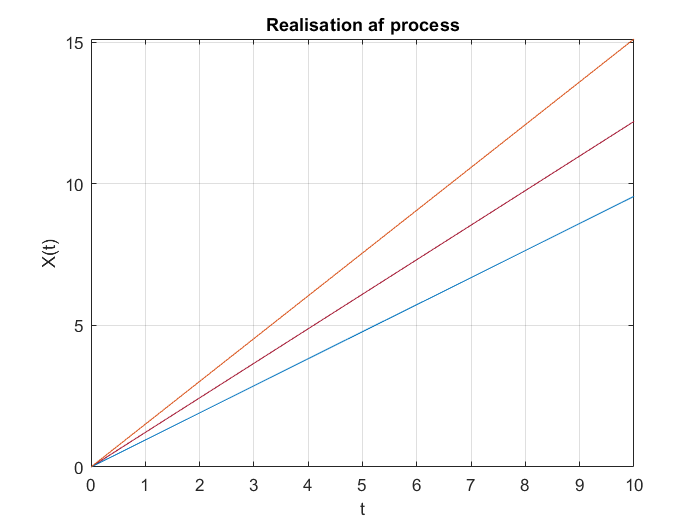

clear all
close all
syms t
N = 3; % Antal realisationer
mean = 1; variance = 0.25; sigma = sqrt(variance);
a = mean + sigma .* randn(1,N);
figure()
for i = 1:N
    y = a*t;
    fplot(y,[0 10])
    hold on
end
grid on;
xlabel("t"); ylabel("X(t)"); title("Realisation af process");